load("DREAMER.mat"); % load DREAMER dataset

## Basic Vars

samplingRate = DREAMER.EEG_SamplingRate; % retrieve sampling rate
windowSize = 256; % window size for each data segment in PSD (power spectral density) calculation
overlap = 128; % overlap between segments

freqRanges = [
    4, 8;      % Theta band: 4 - 8 Hz
    8, 13;     % Alpha band: 8 - 13 Hz
    13, 30;    % Beta band: 13 - 30 Hz
    30, 100;   % Gamma band: 30 - 100 Hz
];

## Subject 1 Film 1 Test

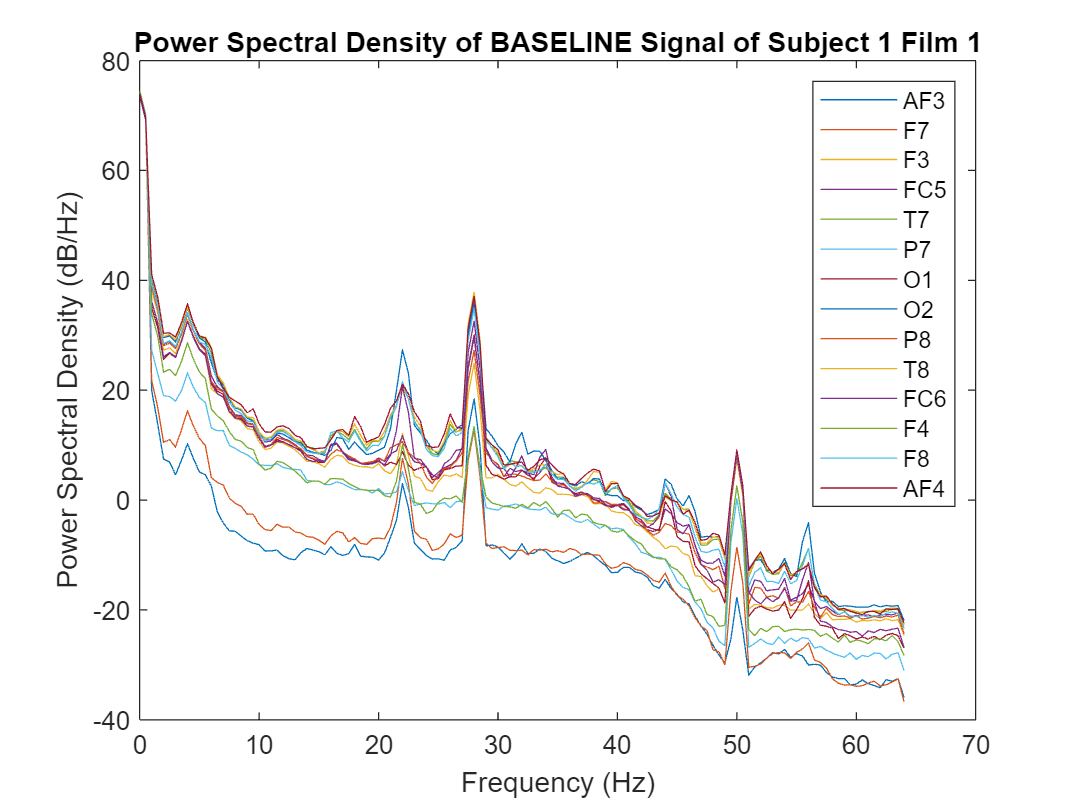

% baseline feature extraction (last 60s)
EEG_baseline = DREAMER.Data{1}.EEG.baseline{1}; % load baseline EEG signal for subject 1 film 1
baseline_last_60s = EEG_baseline(end-samplingRate*60+1:end, :);
[psd, freq] = getPSD(baseline_last_60s, windowSize, overlap, samplingRate);
graphPSD(freq, psd, 'baseline', 1, 1, DREAMER.EEG_Electrodes);

baseline_features = extractEEGFeatures(freq, psd, freqRanges);

% verification
psd, freq, baseline_features

psd = 1.0e+07 *

    2.7993    2.4427    2.5132    2.7952    2.6748    2.7978    2.8423    2.2960    2.7006    2.6315    2.2622    2.8552    2.6661    2.5337
    1.0262    0.8955    0.9200    1.0230    0.9789    1.0262    1.0419    0.8410    0.9883    0.9631    0.8286    1.0456    0.9758    0.9269
    0.0000    0.0000    0.0007    0.0009    0.0011    0.0001    0.0003    0.0011    0.0008    0.0012    0.0004    0.0002    0.0009    0.0013
    0.0000    0.0000    0.0003    0.0003    0.0004    0.0000    0.0001    0.0004    0.0003    0.0005    0.0002    0.0001    0.0003    0.0005
    0.0000    0.0000    0.0001    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001
    0.0000    0.0000    0.0001    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001    0.0001    0.0000    0.0000    0.0001    0.0

freq =          0
    0.5000
    1.0000
    1.5000
    2.0000
    2.5000
    3.0000
    3.5000
    4.0000
    4.5000


baseline_features =    13.0754   18.7006   35.1290   36.2960   37.6232   26.2284   35.0669   37.3693   36.0357   37.9058   34.9307   30.9238   36.7146   38.0420
    1.5863    6.4157   21.6561   22.7123   23.6502   17.0748   22.0834   23.4103   22.4221   23.8055   22.0176   17.9939   23.2096   24.7846
   20.1721   16.1295   27.5436   34.3661   38.5314   18.9734   31.9462   38.2242   29.7289   39.6149   32.1072   19.5226   36.8834   39.0158
    3.8402    4.7090   15.9645   17.8046   19.1923   11.5174   17.6663   20.9176   17.2646   19.4218   18.5786   12.1949   19.0121   19.8836


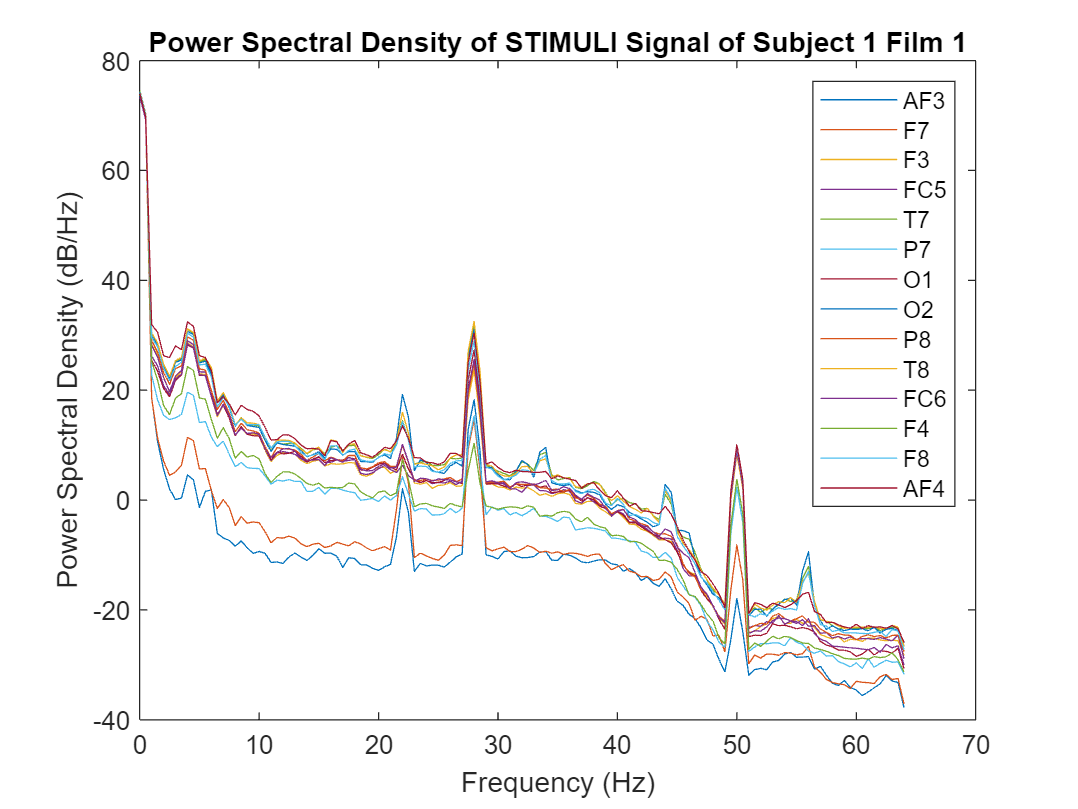


% stimuli feature extraction (last 60s)
EEG_stimuli = DREAMER.Data{1}.EEG.stimuli{1}; % load stimuli EEG signal for subject 1 film 1
stimuli_last_60s = EEG_stimuli(end-samplingRate*60+1:end,:);
[psd, freq] = getPSD(stimuli_last_60s, windowSize, overlap, samplingRate);
graphPSD(freq, psd, 'stimuli', 1, 1, DREAMER.EEG_Electrodes);

stimuli_features = extractEEGFeatures(freq, psd, freqRanges);
stimuli_features_normalized = stimuli_features-baseline_features;

stimuli_features, stimuli_features_normalized

stimuli_features =     9.1270   14.8426   31.9714   32.3919   34.5493   23.4853   31.7656   34.2586   33.0278   34.7504   31.8329   27.6608   33.8204   35.5372
    0.3477    4.7753   20.5029   20.6558   22.3127   14.9038   20.5729   22.1396   21.2403   22.5879   20.7852   16.4890   22.4098   24.3757
   19.9491   17.2861   26.4210   32.1910   33.7056   19.2471   29.4455   33.1513   27.4808   34.4229   28.0197   17.9795   31.2298   32.5778
    3.6094    4.6626   15.6617   16.1055   19.1812   11.0270   16.2713   18.8259   16.4686   18.9034   16.6453   11.9589   18.4399   18.6550


stimuli_features_normalized =    -3.9484   -3.8579   -3.1575   -3.9041   -3.0739   -2.7430   -3.3013   -3.1107   -3.0079   -3.1554   -3.0978   -3.2630   -2.8942   -2.5048
   -1.2386   -1.6404   -1.1531   -2.0564   -1.3375   -2.1710   -1.5104   -1.2707   -1.1818   -1.2176   -1.2324   -1.5049   -0.7997   -0.4088
   -0.2230    1.1566   -1.1226   -2.1751   -4.8258    0.2737   -2.5007   -5.0730   -2.2481   -5.1919   -4.0875   -1.5432   -5.6536   -6.4380
   -0.2308   -0.0464   -0.3027   -1.6990   -0.0111   -0.4904   -1.3951   -2.0917   -0.7961   -0.5184   -1.9333   -0.2361   -0.5722   -1.2286


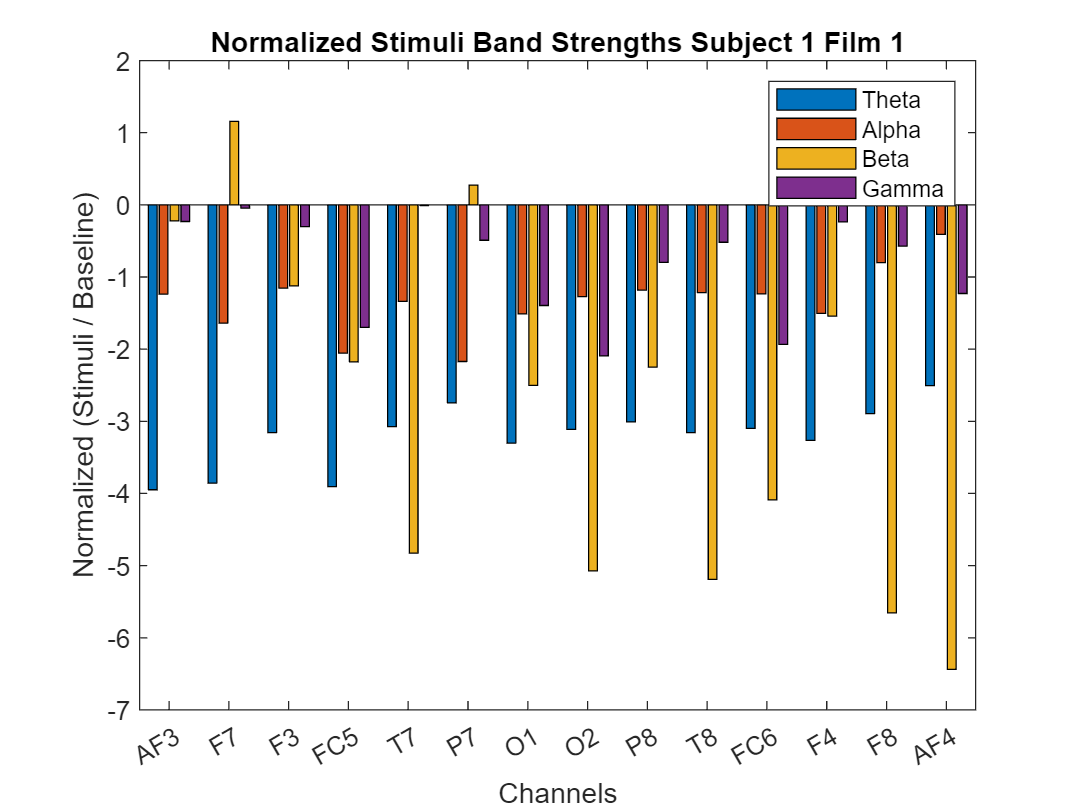


% normalized feature graph
graphFeatures(stimuli_features_normalized, 1, 1, DREAMER.EEG_Electrodes);

## Subject 1 Film 2 Test

% baseline feature extraction (last 60s)
EEG_1_baseline_2 = DREAMER.Data{1}.EEG.baseline{2};
baseline_last_60s = EEG_1_baseline_2(end-samplingRate*60+1:end, :);
[psd, freq] = getPSD(baseline_last_60s, windowSize, overlap, samplingRate);
baseline_features = extractEEGFeatures(freq, psd, freqRanges);

% stimuli feature extraction (last 60s)
EEG_1_stimuli_2 = DREAMER.Data{1}.EEG.stimuli{2};
stimuli_last_60s = EEG_1_stimuli_2(end-samplingRate*60+1:end,:);
[psd, freq] = getPSD(stimuli_last_60s, windowSize, overlap, samplingRate);
stimuli_features = extractEEGFeatures(freq, psd, freqRanges);
stimuli_features_normalized = stimuli_features-baseline_features;
stimuli_features_normalized

stimuli_features_normalized =    -0.5470   -2.2208   -2.6112   -2.5580   -2.2253   -1.8870   -2.1015   -2.1981   -2.0383   -2.2162   -2.2099   -2.1637   -2.2419   -1.9281
   -0.9412   -1.9412   -1.6364   -1.5797   -1.5701   -1.3091   -1.5097   -1.3542   -1.2967   -1.3248   -1.1691   -1.6415   -1.1839   -1.3236
   -0.2325    0.4024   -0.4522   -0.1170    0.2092    0.2468   -0.1642    0.4518   -0.0964    0.1559   -0.2586   -0.5036    0.0570   -4.3145
    0.2053   -0.6750   -0.9236   -0.8582   -0.5212   -0.6444   -0.7378   -0.1552   -0.6005   -0.4511   -0.7572   -0.7164   -0.6547   -1.5883


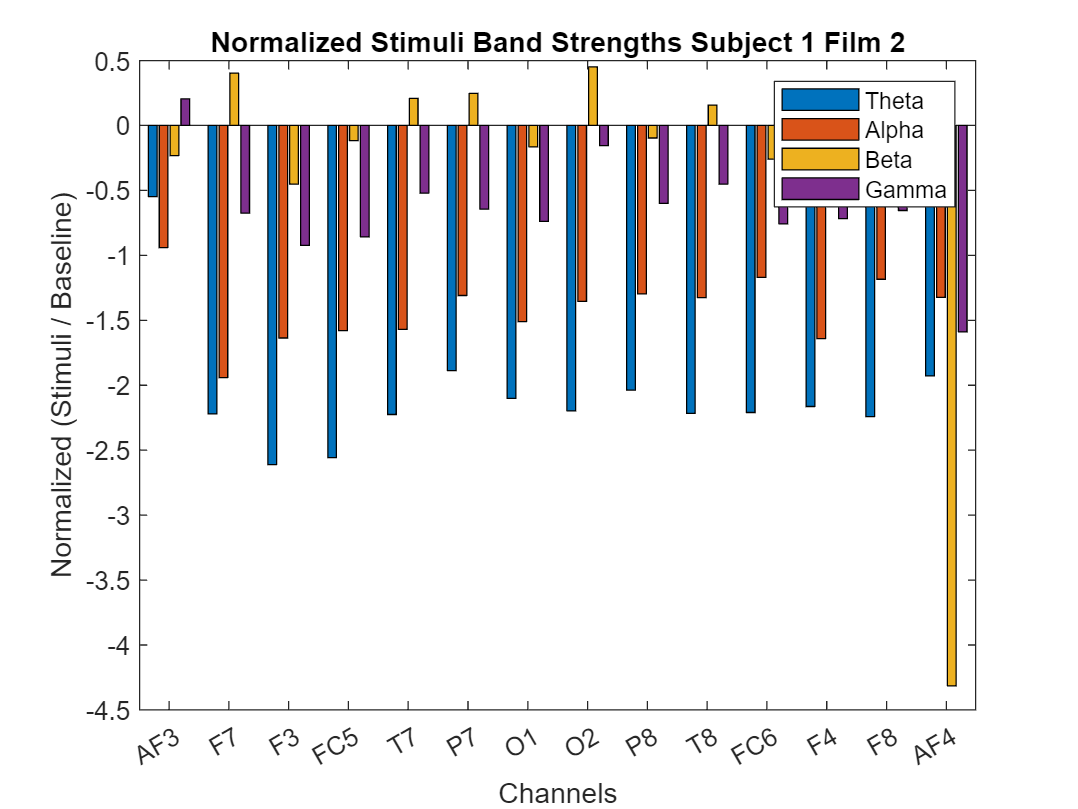


% normalized feature graph
graphFeatures(stimuli_features_normalized, 1, 2, DREAMER.EEG_Electrodes);

## Subject 1 Scores Test

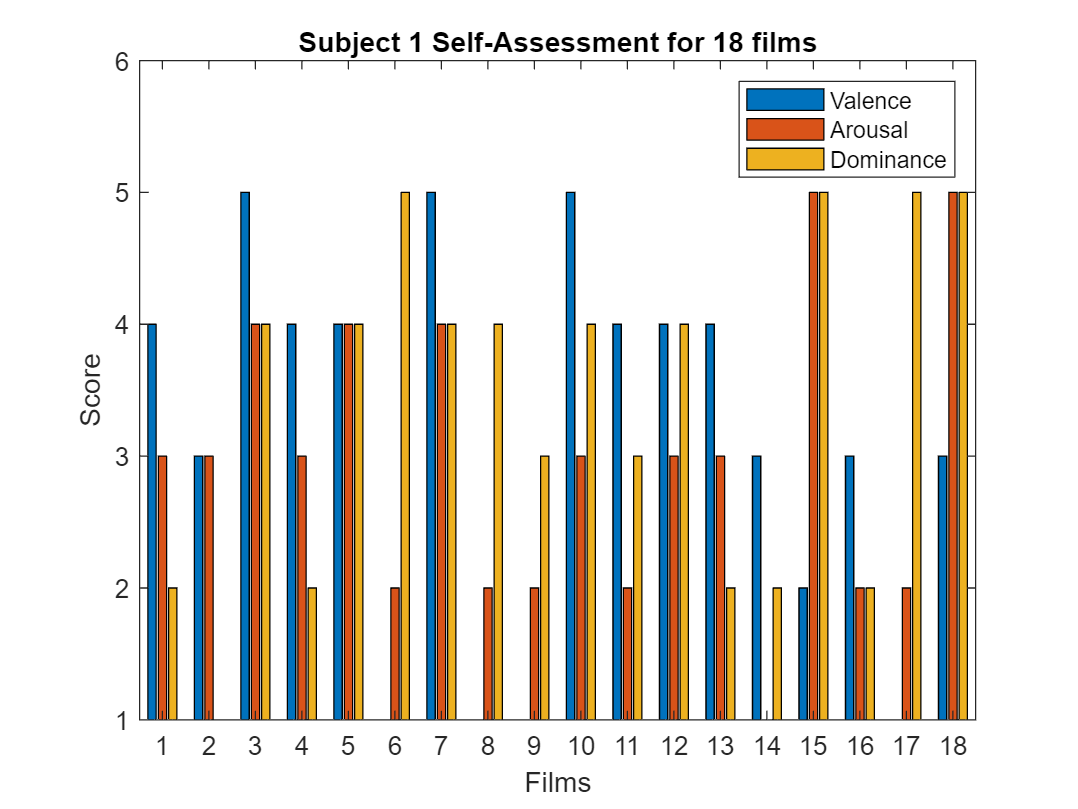

% subject 1 scoring EDA
graphScores(DREAMER, 1);

## Function Declarations

function [psd, freq] = getPSD(eegSignal, windowSize, overlap, samplingRate)
    [psd, freq] = pwelch(eegSignal, windowSize, overlap, windowSize, samplingRate); % use Welch's method to calculate PSD
end

function graphPSD(freq, psd, type, subjectId, filmId, channelNames)
    plot(freq, 10*log10(psd)); % convert to dB when graphing
    xlabel('Frequency (Hz)');
    ylabel('Power Spectral Density (dB/Hz)');
    title(compose('Power Spectral Density of %s Signal of Subject %d Film %d', upper(type), subjectId, filmId));
    legend(channelNames);
end

function features = extractEEGFeatures(freq, psd, freqRanges)
    features = zeros(3, 14); % init features with 3 bands and 14 channels
    for i = 1:size(freqRanges)
        curBand = freqRanges(i, :);
        features(i, :) = trapz(psd(freq >= curBand(1) & freq <= curBand(2), :));
    end
    features = 10*log10(features);
end

function graphFeatures(features, subjectId, filmId, channelNames)
    bar(transpose(features), 'grouped');
    xlabel('Channels');
    xticklabels(channelNames);
    ylabel('Normalized (Stimuli / Baseline)');
    title(compose('Normalized Stimuli Band Strengths Subject %d Film %d', subjectId, filmId));
    legend({'Theta', 'Alpha', 'Beta', 'Gamma'});
end

function graphScores(DREAMER, subjectId)
    scoreCategories = {'Valence', 'Arousal', 'Dominance'};
    scores = [DREAMER.Data{subjectId}.ScoreValence, DREAMER.Data{subjectId}.ScoreArousal, DREAMER.Data{subjectId}.ScoreDominance]; % load self-assessment scores for subjectId
    bar(scores, 'grouped'); % plot a grouped bar graph with each group representing one of 18 films
    xlabel('Films');
    xticks(1:18);
    ylabel('Score');
    ylim([1,6]);
    yticks(1:6);
    title(compose('Subject %d Self-Assessment for 18 films', subjectId));
    legend(scoreCategories);
end